**2.2.1 Example Discrete-time Systems**

i&ii. formulate a discrete-time system and write down the difference equation

    1. differentiator y[n]=x[n]-x[n-1]

    a=[1]; 

    b=[1 -1];

    y=filter(b,a,x);

    2. integrator y[n]=x[n]+y[n-1]

    a=[1 -1]; 

    b=[1];

    y=filter(b,a,x);

iii. draw a diagram

**2.2.2 Stock Market Example**

(1) difference equation

y1[n]=(x[n]+x[n-1]+x[n-2])/3

y2[n]=0.8*y2[n-1]+0.2*x[n]

y3[n]=y3[n-1]+(x[n]-x[n-3])/3

(3) impulse response

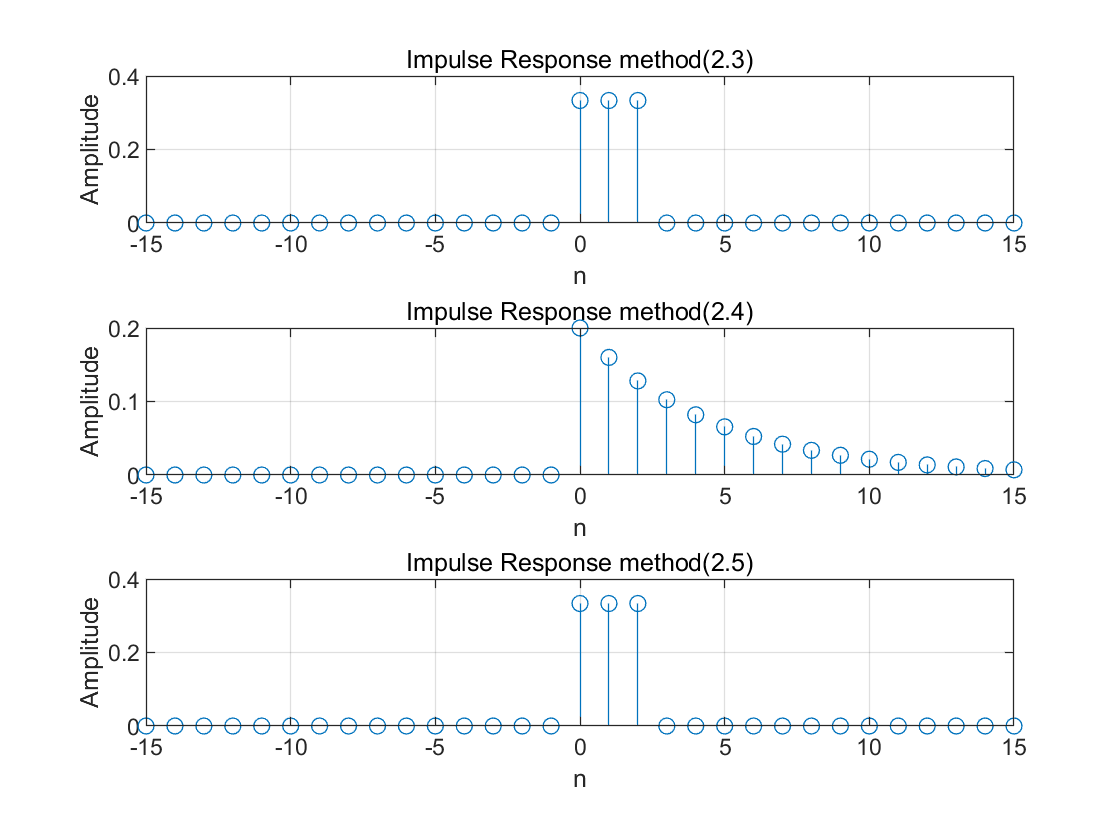

n=-15:15;
x=[n==0];%%delta input
a1=[1];b1=[1/3 1/3 1/3];
a2=[1 -0.8];b2=[0.2];
a3=[1 -1]; b3=[1/3 0 0 -1/3];
y1=filter(b1,a1,x);
y2=filter(b2,a2,x);
y3=filter(b3,a3,x);
% the impulse response
figure;
subplot(3, 1, 1);
stem(n, y1);
title('Impulse Response method(2.3)');
xlabel('n');ylabel('Amplitude');grid on;

subplot(3, 1, 2);
stem(n, y2);
title('Impulse Response method(2.4)');
xlabel('n');ylabel('Amplitude');grid on;


subplot(3, 1, 3);
stem(n, y3);
title('Impulse Response method(2.5)');
xlabel('n');ylabel('Amplitude');grid on;

- Explain why methods (2.3) and (2.5) are known as moving averages.

method(2.3) y1[n]: This method represents a simple moving average filter.The difference equation for y1[n] is given by:y1[n] = (x[n] + x[n-1] + x[n-2]) / 3

In this filter, each output sample y1[n] is calculated as the average of the current input sample x[n] and the two previous input samples x[n-1] and x[n-2]. It effectively smoothes the input signal by providing an average value over a window of three samples, making it a moving average filter.

method(2.5) y3[n]:This method represents a cumulative moving average filter. The difference equation for y3[n] is given by:y3[n] = y3[n-1] + (x[n] - x[n-3]) / 3

In this filter, each output sample y3[n] is calculated as the cumulative average of the current input sample x[n] and the input sample from three time steps ago, x[n-3]. It continuously updates the average as new input samples arrive, making it a moving average filter with a cumulative effect.

**2****.3 Example Discrete-Time Systems**

Firstly, let's us write two Matlab functions that will apply the differentiator and integrator systems, designed in the Section 2.2.1, to arbitrary input signals. 

1.differentiator

function y=differentiator(x)

% Implement the differentiator system

        % Difference equation coefficients for differentiator

    a = [1];    b = [1 -1];

        % Apply the filter to the input signal

    y = filter(b, a, x);

end

2. integrator

function y=integrator(x)

    % Implement the integrator system

        % Difference equation coefficients for integrator

    a = [1 -1];

    b = [1];

        % Apply the filter to the input signal

    y = filter(b, a, x);

end

Now, let's use these functions to apply the differentiator and integrator systems to the provided input signals and plot the results:

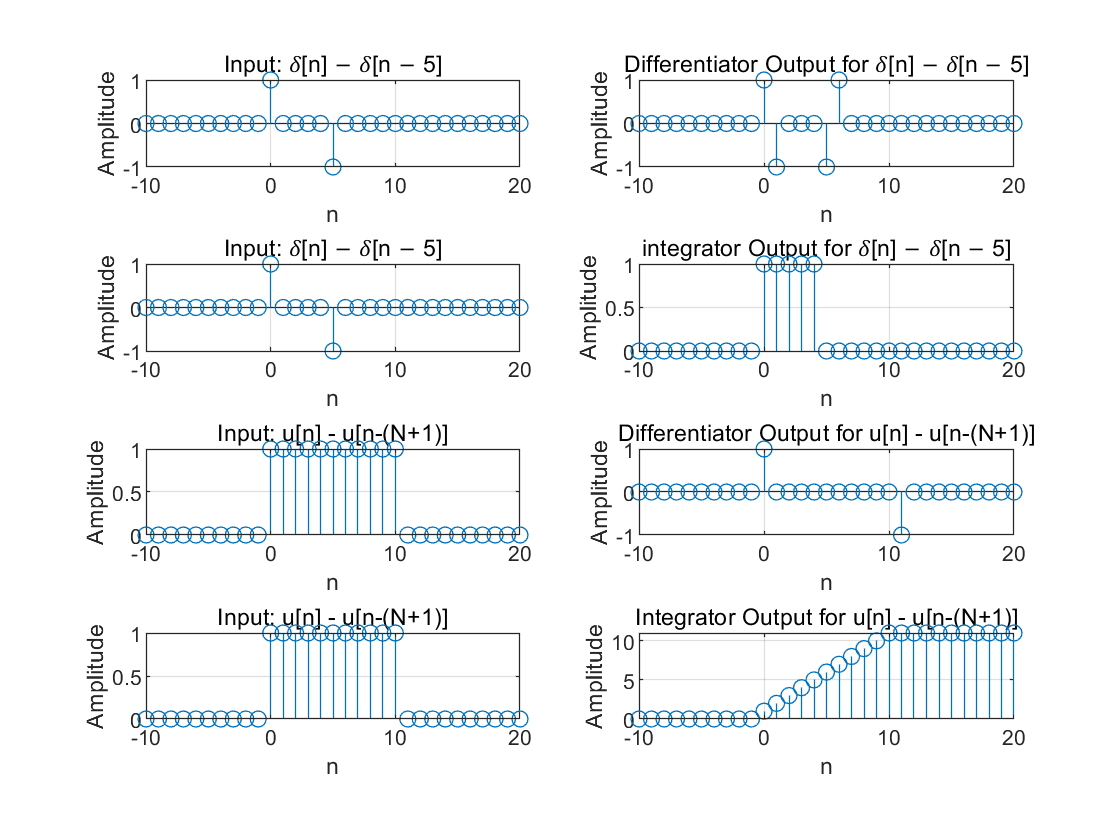

% Define the input signals
n = -10:20;
delta_signal=(n==0)-(n==5);%input signal of 𝛿[n] − 𝛿[n − 5]
N = 10;
u_signal = (n >= 0) - (n >= N + 1);%input signal of 𝑢[n] − 𝑢[𝑛 − (𝑁 + 1)] with N = 10
% Apply the differentiator and integrator to the input signals
y1_diff = differentiator(delta_signal);
y2_diff = differentiator(u_signal);
y1_int = integrator(delta_signal);
y2_int = integrator(u_signal);

% Create a single figure with subplots to visualize the results
figure;

% Subplot 1: Input delta[n] - delta[n-5]
subplot(4, 2, 1);
stem(n, delta_signal);
title('Input: 𝛿[n] − 𝛿[n − 5]');
xlabel('n');ylabel('Amplitude');grid on;

% Subplot 2: Differentiator Output for delta[n] - delta[n-5]
subplot(4, 2, 2);
stem(n, y1_diff);
title('Differentiator Output for 𝛿[n] − 𝛿[n − 5]');
xlabel('n');ylabel('Amplitude');grid on;

% Subplot 3: Input delta[n] - delta[n-5]
subplot(4, 2, 3);
stem(n, delta_signal);
title('Input: 𝛿[n] − 𝛿[n − 5]');
xlabel('n');ylabel('Amplitude');grid on;

% Subplot 4: integrator Output for delta[n] - delta[n-5]
subplot(4, 2, 4);
stem(n, y1_int);
title('integrator Output for 𝛿[n] − 𝛿[n − 5]');
xlabel('n');ylabel('Amplitude');grid on;

% Subplot 5: Input u[n] - u[n-(N+1)]
subplot(4, 2, 5);
stem(n, u_signal);
title('Input: u[n] - u[n-(N+1)]');
xlabel('n');ylabel('Amplitude');grid on;

% Subplot 6: Differentiator Output for u[n] - u[n-(N+1)]
subplot(4, 2, 6);
stem(n, y2_diff);
title('Differentiator Output for u[n] - u[n-(N+1)]');
xlabel('n');ylabel('Amplitude');grid on;
% Subplot 7: Input u[n] - u[n-(N+1)]
subplot(4, 2, 7);
stem(n, u_signal);
title('Input: u[n] - u[n-(N+1)]');
xlabel('n');ylabel('Amplitude');grid on;

% Subplot 8: Integrator Output for u[n] - u[n-(N+1)]
subplot(4, 2, 8);
stem(n, y2_int);
title('Integrator Output for u[n] - u[n-(N+1)]');
xlabel('n');ylabel('Amplitude');grid on;

**2.4 Difference Equation**

% Define S1 filter function

function y = S1(x)

    N = length(x);

    y = zeros(1, N); % Pre-define the output vector

    for n = 1:N

        if n == 1

            y(n) = x(n); % Initial condition

        else

            y(n) = x(n) - x(n - 1);

        end

    end

end

% Define S2 filter function

function y = S2(x)

    N = length(x);

    y = zeros(1, N); % Pre-define the output vector

    for n = 1:N

        if n == 1

            y(n) = x(n); % Initial condition

        else

            y(n) = y(n - 1) / 2 + x(n);

        end

    end

end

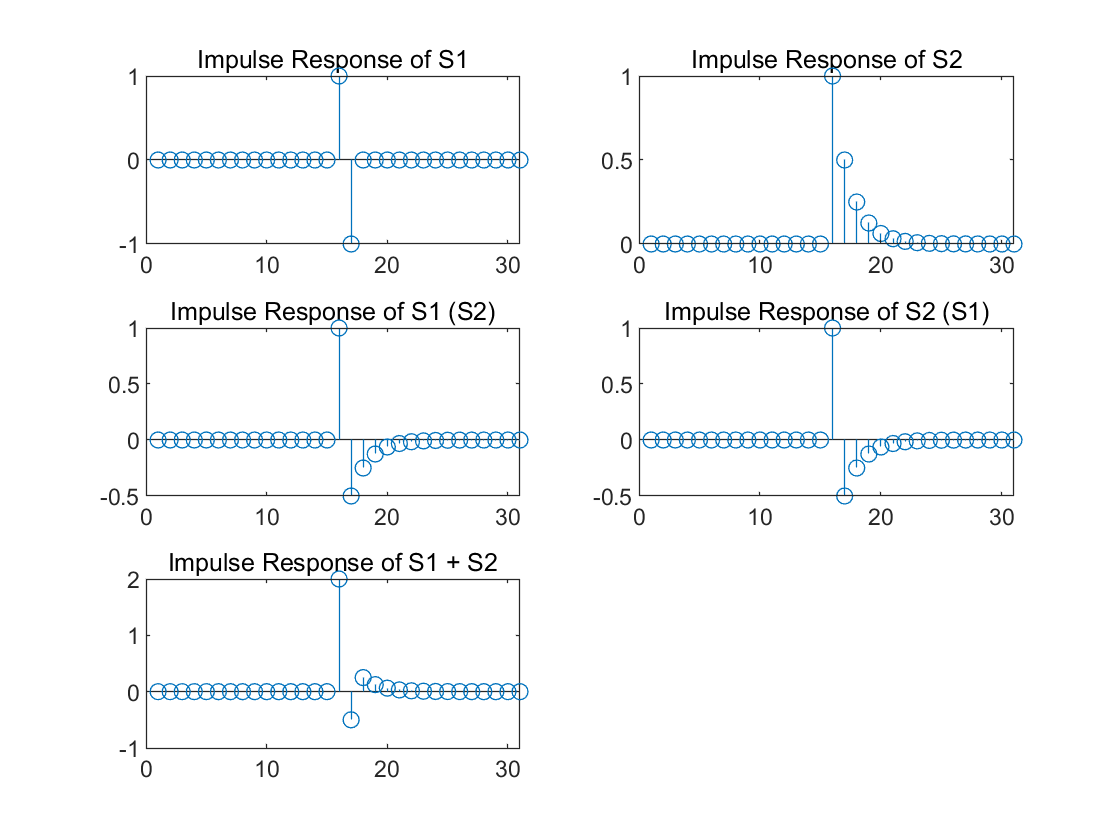

n=-15:15;
impulse = (n==0); % Impulse signal 𝛿[n] 

% Calculate impulse responses for each system
impulse_response_S1 = S1(impulse);
impulse_response_S2 = S2(impulse);
impulse_response_S1_S2 = S1(impulse_response_S2);
impulse_response_S2_S1 = S2(impulse_response_S1);
impulse_response_S1_plus_S2 = S1(impulse) + S2(impulse);

% Plot the impulse responses 
figure
subplot(3, 2, 1);
stem(impulse_response_S1);
title('Impulse Response of S1');

subplot(3, 2, 2);
stem(impulse_response_S2);
title('Impulse Response of S2');

subplot(3, 2, 3);
stem(impulse_response_S1_S2);
title('Impulse Response of S1 (S2)');

subplot(3, 2, 4);
stem(impulse_response_S2_S1);
title('Impulse Response of S2 (S1)');

subplot(3, 2, 5);
stem(impulse_response_S1_plus_S2);
title('Impulse Response of S1 + S2');

**2.5 Audio Filtering**

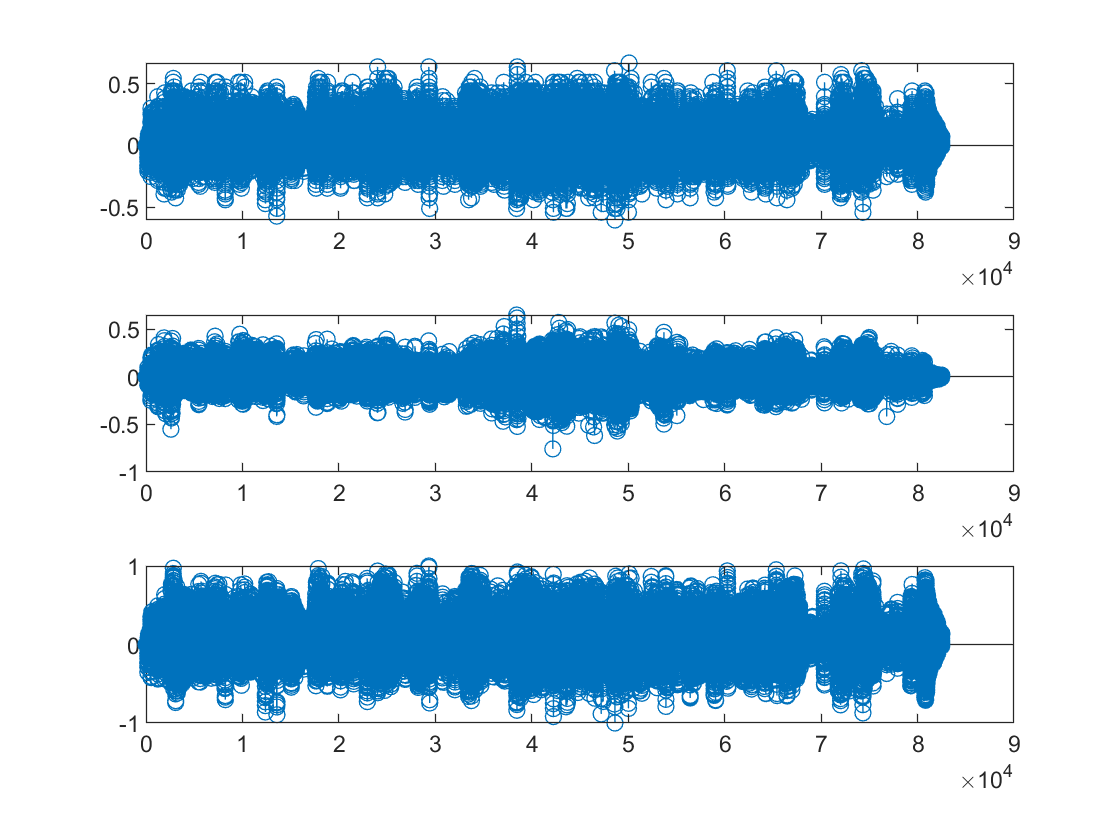

audio=audioread('music.au');
audio_S1=S1(audio);
audio_S2=S2(audio);
%sound(audio)
%sound(audio_S1)
sound(audio_S2);
figure
subplot(3,1,1),stem(audio)
subplot(3,1,2),stem(audio_S1)
subplot(3,1,3),stem(audio_S2)

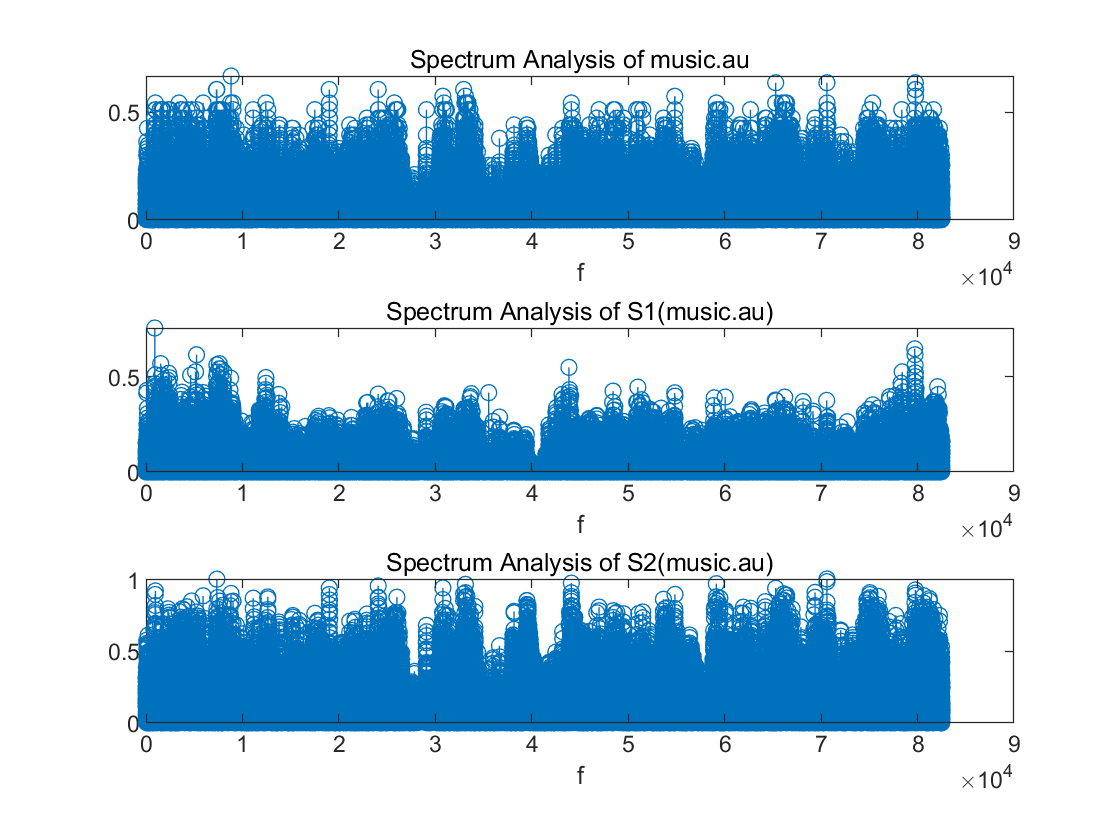



figure
subplot(3,1,1),stem(abs(fftshift(audio))),title('Spectrum Analysis of music.au');xlabel('f')
subplot(3,1,2),stem(abs(fftshift(audio_S1))),title('Spectrum Analysis of S1(music.au)');xlabel('f')
subplot(3,1,3),stem(abs(fftshift(audio_S2))),title('Spectrum Analysis of S2(music.au)');xlabel('f')

**2.6 Inverse Systems**

we can use MATLAB to solve for the values of a and b using symbolic algebra.

S2:   y2(n) = y2(n - 1) / 2 + x2(n); 

S3:   𝑦3[n] = 𝑎𝑥3[𝑛] + 𝑏𝑥3[𝑛 − 1]

when input signal is an impulss signal ,impulse input signal==output of S3(S2(impulse))

% Create an input impulse signal 
n=-15:15;
impulse = (n==0)

impulse = 1×31 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


syms a b

% Solve the equations
eq1 = impulse(16) ==a*impulse_response_S2(16)+b*impulse_response_S2(15)

$$eq1 = 1=a$$

eq2 = impulse(17) ==a*impulse_response_S2(17)+b*impulse_response_S2(16)

$$eq2 = 0=\frac{a}{2}+b$$


% Solve for a and b
solution = solve([eq1, eq2], [a, b]);

% Extract the values of a and b
a_value = solution.a

$$a\_value = 1$$

b_value = solution.b

$$b\_value = -\frac{1}{2}$$

Now that we have obtained the values of a and b, we can use these values to construct the difference equation for the system S3, and write a Matlab function *y* = ***S***3(*x*) which implements the system ***S***3.

Next, let's write a MATLAB function to implement the system S3 and compute the impulse responses of S3 and S3(S2(x)). Here's the MATLAB code:

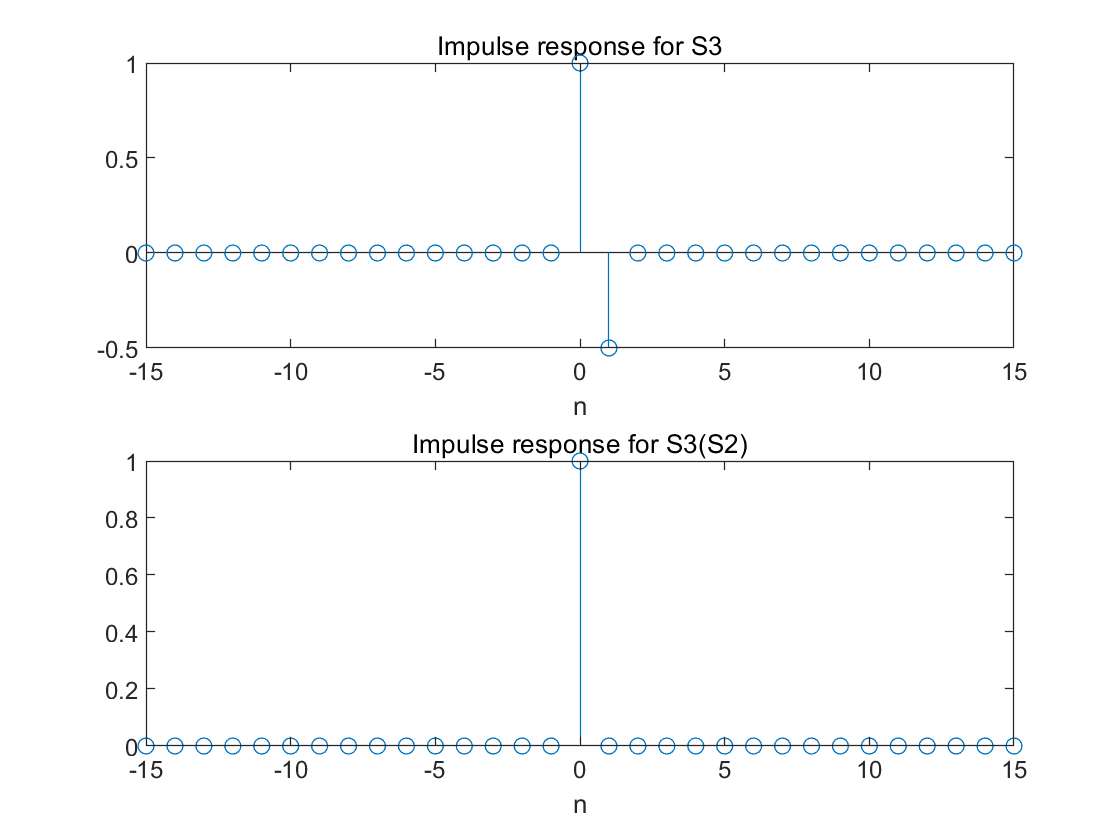

% Compute the impulse response of S3
impulse_response_S3 = S3(impulse);

% Compute the impulse response of S3(S2(x))
impulse_response_S3_S2 = S3(impulse_response_S2);

figure
subplot(2,1,1),stem(n,impulse_response_S3),xlabel('n'),title('Impulse response for S3');
subplot(2,1,2),stem(n,impulse_response_S3_S2),xlabel('n'),title('Impulse response for S3(S2)');

**2.7 System Tests **

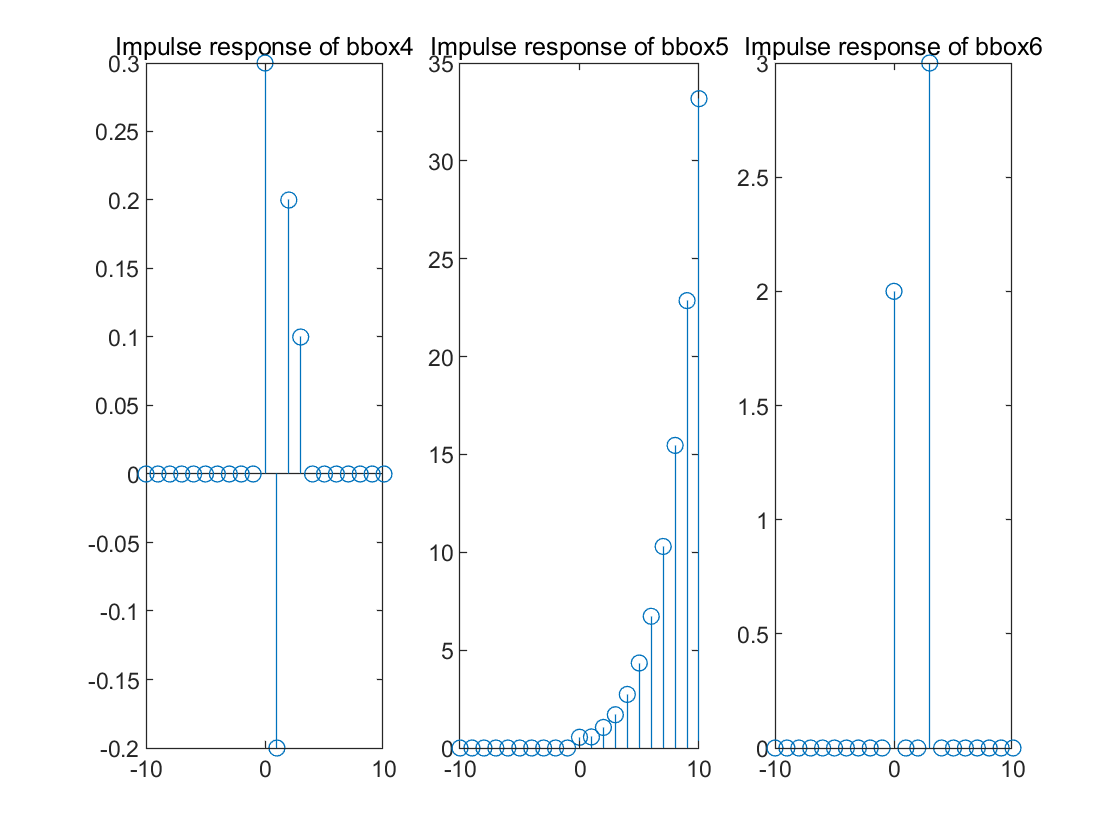

%firstly, observe three systems
n=-10:10;
impulse=(n==0);

h1=bbox4(impulse);
h2=bbox5(impulse);
h3=bbox6(impulse);
figure 
subplot(1,3,1),stem(n,h1),title('Impulse response of bbox4')
subplot(1,3,2),stem(n,h2),title('Impulse response of bbox5')
subplot(1,3,3),stem(n,h3),title('Impulse response of bbox6')

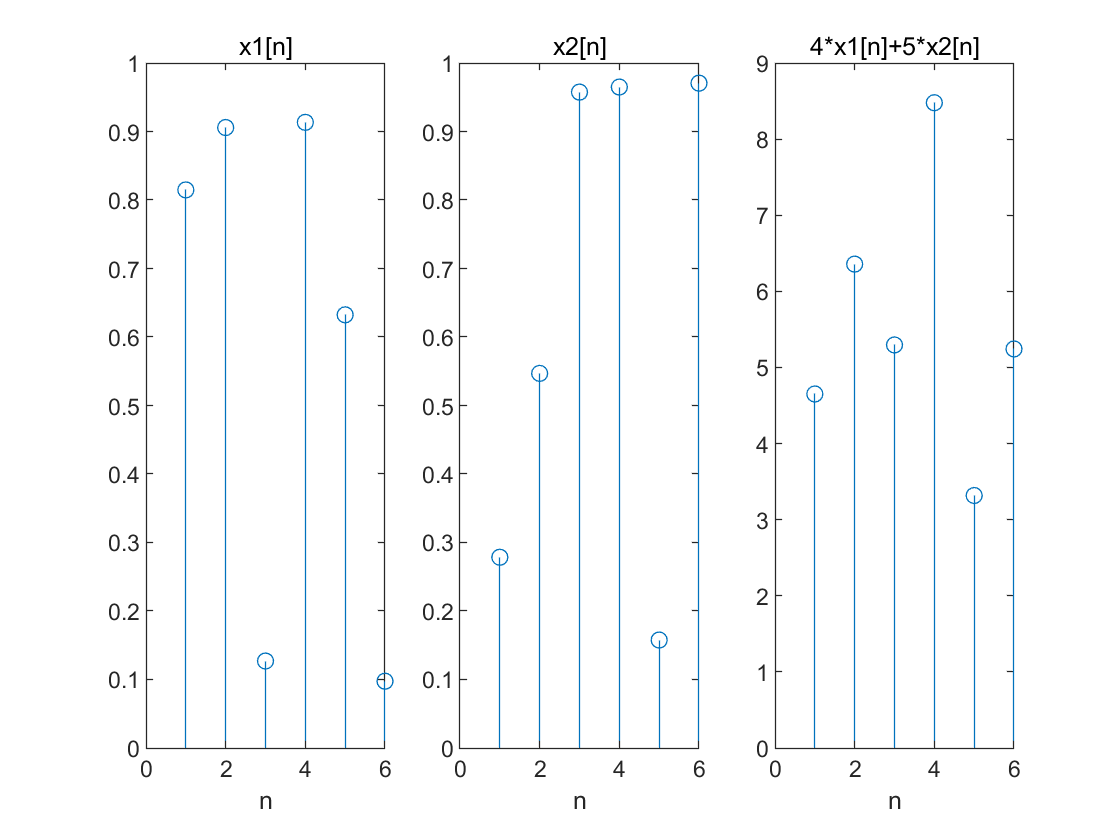

% 先测试是否线性
% check if bbox(ax1[n]+bx2[n])=a*bbox(x1[n])+ b*bbox(x2[n])
x1=rand(1,6);x2=rand(1,6);
%Using the random function rand, so each time it runs, the input signal is different
%meeting the requirement to "try a variety of input signals until you find a counter-example."
figure
subplot(1,3,1),stem(x1),xlabel('n'),title('x1[n]');
subplot(1,3,2),stem(x2),xlabel('n'),title('x2[n]');
subplot(1,3,3),stem(4*x1+5*x2),xlabel('n'),title('4*x1[n]+5*x2[n]');

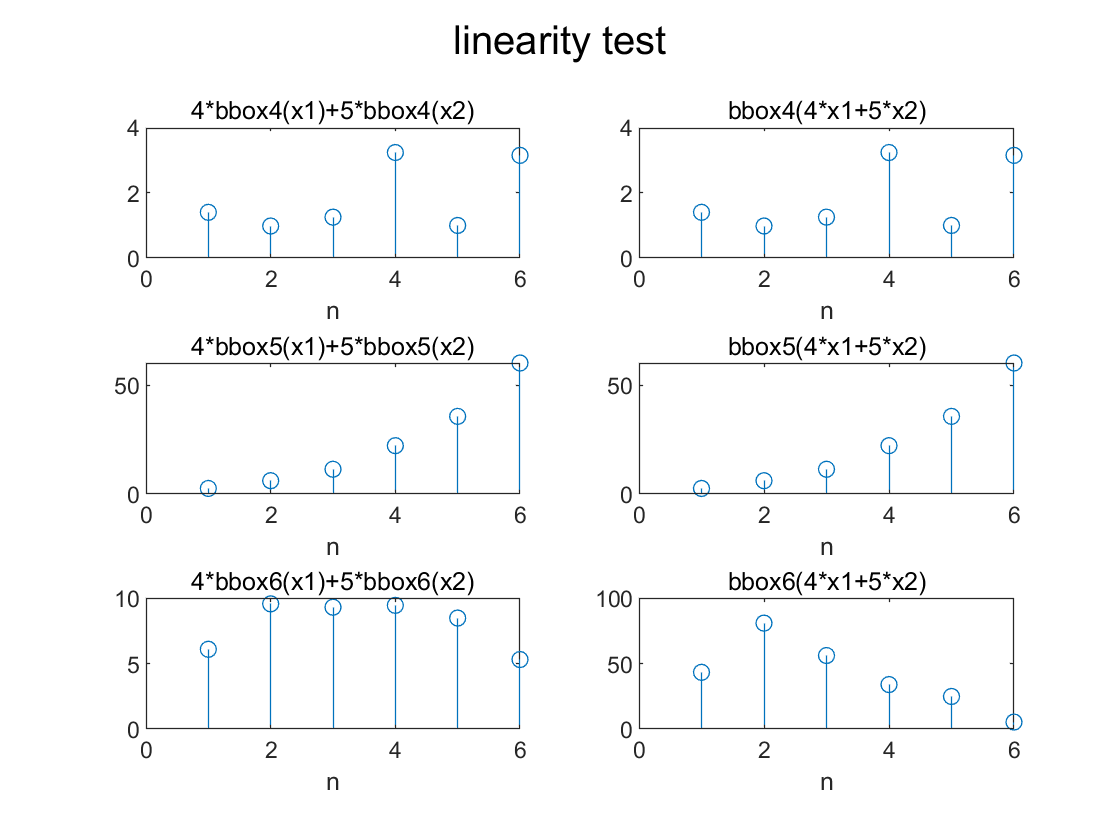


figure
sgtitle('linearity test')
% bbox4
subplot(3,2,1),stem(4*bbox4(x1)+5*bbox4(x2)),xlabel('n'),title('4*bbox4(x1)+5*bbox4(x2)');
subplot(3,2,2),stem(bbox4(4*x1+5*x2)),xlabel('n'),title('bbox4(4*x1+5*x2)');
% bbox5
subplot(3,2,3),stem(4*bbox5(x1)+5*bbox5(x2)),xlabel('n'),title('4*bbox5(x1)+5*bbox5(x2)');
subplot(3,2,4),stem(bbox5(4*x1+5*x2)),xlabel('n'),title('bbox5(4*x1+5*x2)');
% bbox6
subplot(3,2,5),stem(4*bbox6(x1)+5*bbox6(x2)),xlabel('n'),title('4*bbox6(x1)+5*bbox6(x2)');
subplot(3,2,6),stem(bbox6(4*x1+5*x2)),xlabel('n'),title('bbox6(4*x1+5*x2)');

Therefor, bbox6 is a non-linear system

time invariance-test

%y[n+N]?=y1[n]
%Step ONE:
%The input signal x[n] is first time-shifted and then passed through the system to obtain y1[n]
N=7;
x=[zeros(1,N),rand(1,N),zeros(1,N)];%input,right shift or left shift<=N samples
x_shift=[rand(1,N),zeros(1,2*N)]%shift input signal x by N samples to the left

x_shift =     0.9595    0.6557    0.0357    0.8491    0.9340    0.6787    0.7577         0         0         0         0         0         0         0         0         0         0         0         0         0         0



y4_x_shift=bbox4(x_shift);%y1[n] for bbox4
y5_x_shift=bbox5(x_shift);%y1[n] for bbox5
y6_x_shift=bbox6(x_shift);%y1[n] for bbox6

%Step TWO:
%now we will find y[n+N]
y4=bbox4(x);y5=bbox5(x);y6=bbox6(x);

y4_shift=[y4(N+1:length(y4)),zeros(1,N)]%y4[n+N]

y4_shift =     0.2872   -0.0458    0.3344    0.0753    0.3067    0.2988    0.1531    0.0669    0.2500    0.0792         0         0         0         0         0         0         0         0         0         0         0


y5_shift=[y5(N+1:length(y5)),zeros(1,N)]%y5[n+N]

y5_shift =     0.5264    0.8078    1.7199    2.6662    4.5983    7.7362   12.3777   19.1131   29.3421   44.2652   65.6705   95.7635  137.0096  191.9274         0         0         0         0         0         0         0


y6_shift=[y6(N+1:length(y6)),zeros(1,N)]%y6[n+N]

y6_shift =     1.8323    0.4712    1.2809    2.2865    0.4935    0.8269    0.9877    0.7775    2.5929    2.0474         0         0         0         0         0         0         0         0         0         0         0


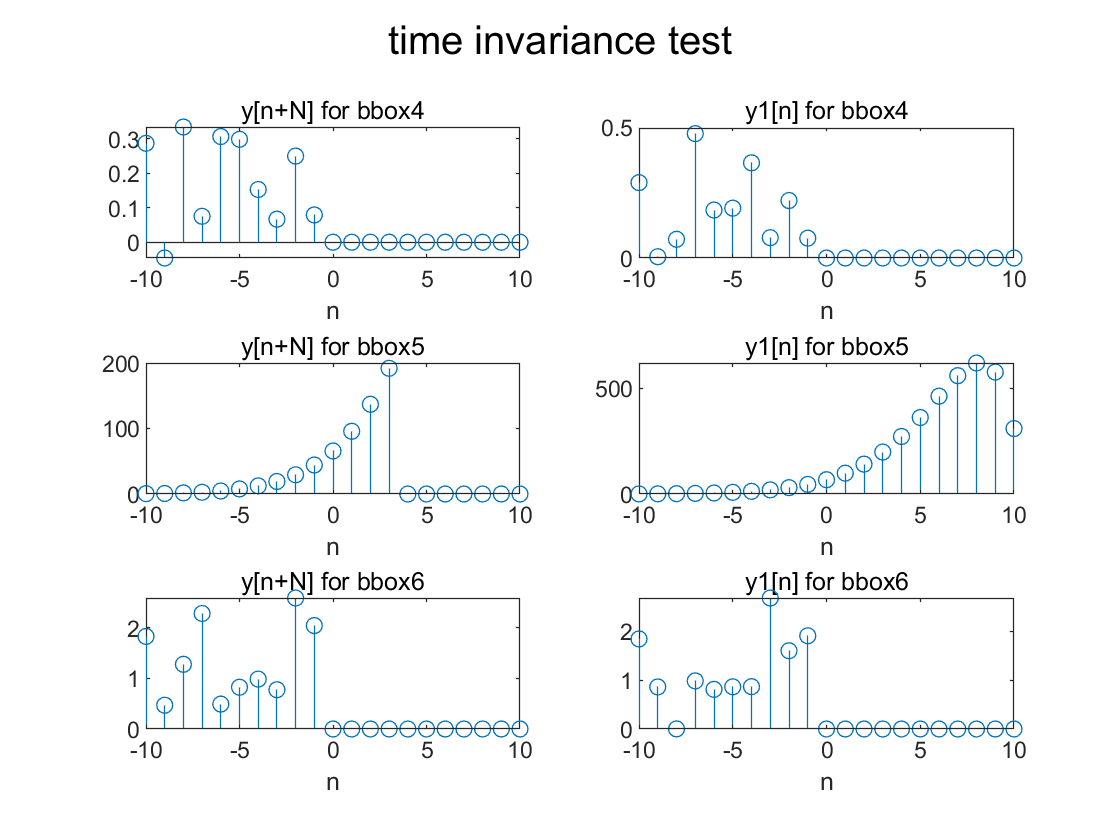



%Step THREE:
% time invariance test:y[n+N]?=y1[n]
n=-10:10;
figure
sgtitle('time invariance test')

% bbox4
subplot(3,2,1),stem(n,y4_shift),title('y[n+N] for bbox4'),xlabel('n');
subplot(3,2,2),stem(n,y4_x_shift),title('y1[n] for bbox4'),xlabel('n');
% bbox5
subplot(3,2,3),stem(n,y5_shift),title('y[n+N] for bbox5'),xlabel('n');
subplot(3,2,4),stem(n,y5_x_shift),title('y1[n] for bbox5'),xlabel('n');
% bbox6
subplot(3,2,5),stem(n,y6_shift),title('y[n+N] for bbox6'),xlabel('n');
subplot(3,2,6),stem(n,y6_x_shift),title('y1[n] for bbox6'),xlabel('n');

结果bbox5时变

**2.8 Stock Market Example**

(2.4) y2[n]=0.8*y2[n-1]+0.2*x[n]

(2.5) y3[n]=y3[n-1]+(x[n]-x[n-3])/3

When you apply the filter of (2.4), you will need to initialize the value of avgvalue(yesterday).

So we construct fiter functions to initialize the filter outputs.

*function y=filter_2_4(x)*

*% y[n]=0.8y[n-1]+0.2x[n]*

*N=length(x);*

*y=zeros(1,N+1);%initialize the value of avgvalue(yesterday)*

*for n=2:N+1*

*y(n)=0.8*y(n-1)+0.2*x(n-1);*

*end*

*y=y(2:N+1);*

*end*

Similarly, in (2.5), set the initial values of the "value" vector to 0 (for the days prior to the start of data collection)

*function y=filter_2_5(x)*

*N=length(x);*

*y=zeros(1,N+1);*

*x=[zeros(1,3) x]; %set the initial values of the "value" vector to 0*

*for n=2:N+1*

*    y(n)=y(n-1)+(1/3)*(x(n+2)-x(n-1));%x(n+3)-x(n)instead of x(n)-x(n-3)*

*end*

*y=y(2:N+1);*

*end*

load stockrates.mat
rate

rate =    46.5000   47.5000   47.5000   47.0000   46.1250   45.2500   45.7500   45.8750   45.6250   44.7500   44.3750   44.7500   44.7500   46.5000   46.5000   47.6250   47.7500   48.1250   48.8750   48.0000   49.7500   49.8750   45.0000   46.0000   46.0000   45.5000   44.6250   43.7500   44.2500   44.3750   44.1250   43.2500   42.8750   43.2500   43.2500   45.0000   45.0000   46.1250   46.2500   46.6250   47.3750   46.5000   48.2500   48.3750


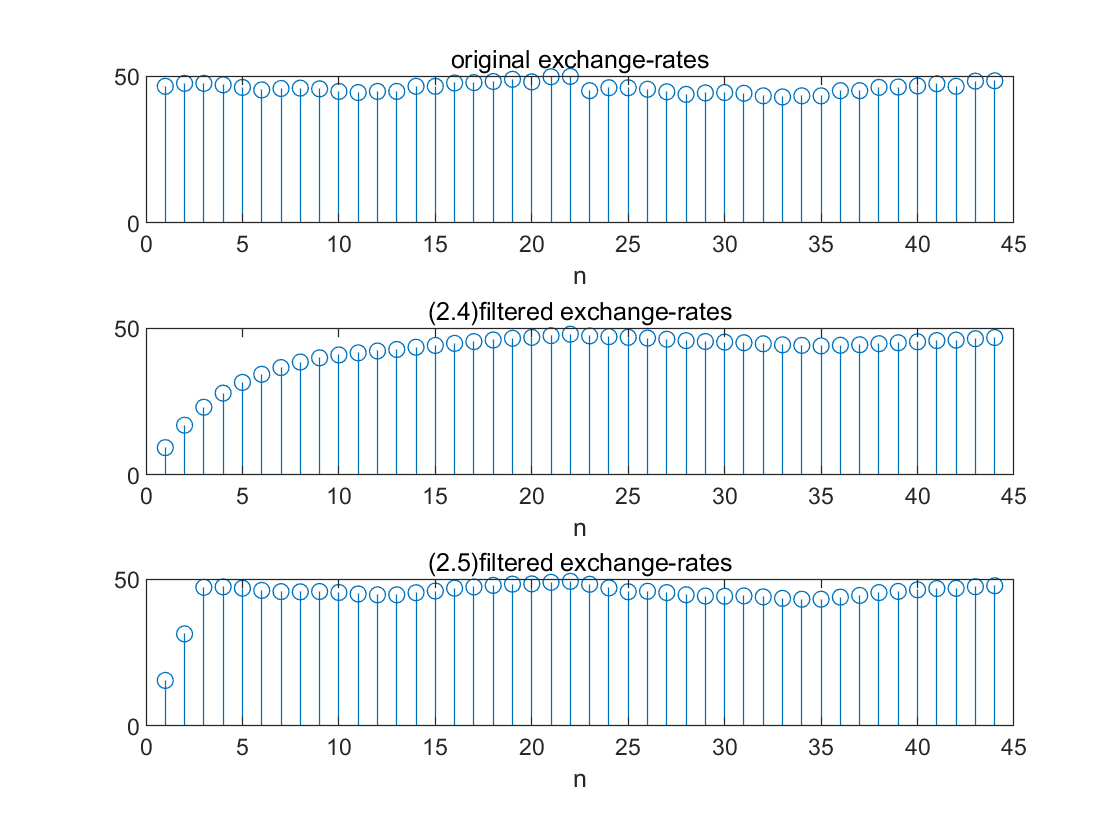

%filter
y2_4=filter_2_4(rate);
y2_5=filter_2_5(rate);
figure
subplot(3,1,1),stem(rate),xlabel('n'),title('original exchange-rates');
subplot(3,1,2),stem(y2_4),xlabel('n'),title('(2.4)filtered exchange-rates');
subplot(3,1,3),stem(y2_5),xlabel('n'),title('(2.5)filtered exchange-rates');